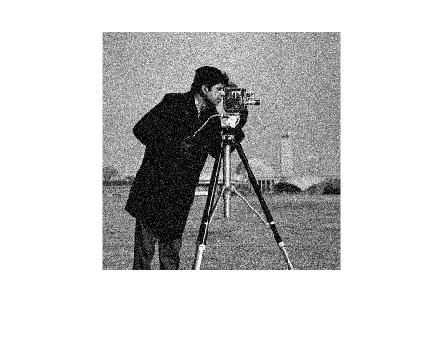

path = "C:\Users\atche\OneDrive\Documents\MATLAB\EE146\Lab4\cameramanGN.tif";
I_gn = imread(path);
imshow(I_gn)

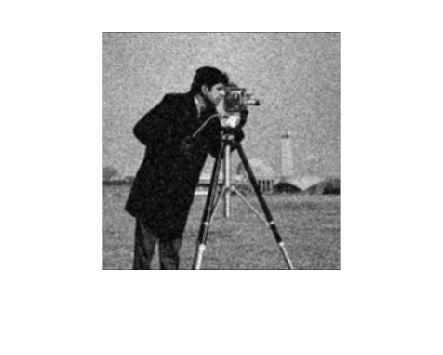

% 3 x 3 mean filter
H = zeros(3,3);
H(1:3, 1:3) = 1/9;
I_mean = imfilter(I_gn, H);

imshow(I_mean)

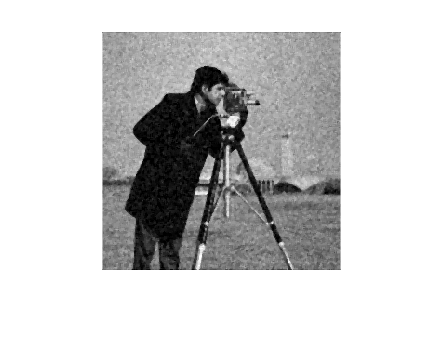

%I_new = double(zeros(size(I_gn, 1), size(I_gn, 2)));

%mean filter implementation without zero padding
% for i = 1:size(I_gn, 1)
%     for j = 1:size(I_gn, 2)
%         if (((i > 1) && (j > 1)) && ((i < 256) && (j < 256)))
%             I_new(i,j) = sum(H .* double(I_gn(i-1:1:i+1,j-1:1:j+1)), "all");
%         else
%             I_new(i,j) = I_gn(i,j);
%         end
%     
%     end
% end
% imshow(uint8(I_new))

I_med = medfilt2(I_gn);
imshow(I_med);

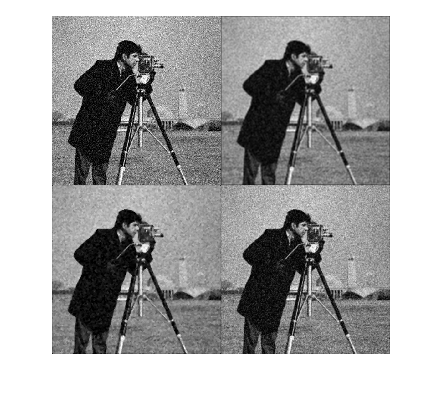

I_gaus = imfilter(I_gn, fspecial('gaussian'));
figure
montage({I_gn, I_mean, I_med, I_gaus})

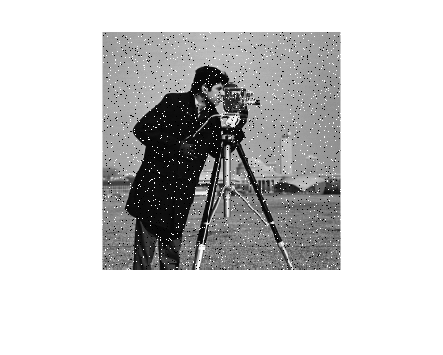

path = "C:\Users\atche\OneDrive\Documents\MATLAB\EE146\Lab4\cameramanSPN.tif";

I_sp = imread(path);
imshow(I_sp)

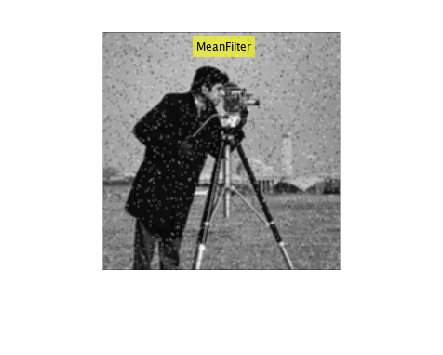

% 3 x 3 mean filter
H = zeros(3,3);
H(1:3, 1:3) = 1/9;
I_mean = imfilter(I_sp, H);
I_mean = insertText(I_mean, [(size(I_mean,1)/2 - 30) 5], "MeanFilter");
imshow(I_mean)

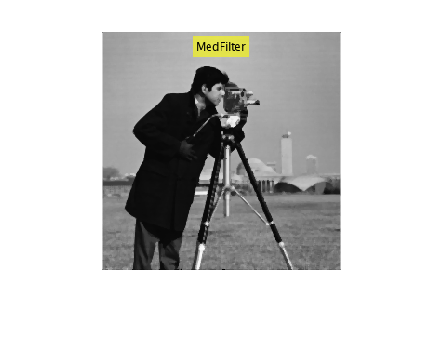

I_new = double(zeros(size(I_sp, 1), size(I_sp, 2)));

I_med = medfilt2(I_sp);
I_med = insertText(I_med, [(size(I_med,1)/2 - 30) 5], "MedFilter");
imshow(I_med);

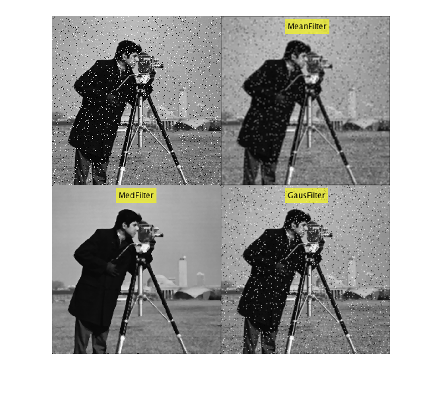


I_gaus = imfilter(I_sp, fspecial('gaussian'));
I_gaus = insertText(I_gaus, [(size(I_gaus,1)/2 - 30) 5], "GausFilter");
figure
montage({I_sp, I_mean, I_med, I_gaus})